# Project

## Q3

clc; clear;

m = 1.5;
d = 0.05;
a = 2;
L = 3;
g = 9.81;

s =tf('s');

Plant = 5*m*g*d/(7*L*s^2) % R/Theta

Plant =
 
  3.679
  ------
  21 s^2
 
Continuous-time transfer function.




Motor = 0.0274/(5*s*(0.003228*s + 0.003508));  %Theta/V

G = Motor * Plant   %   R/V

G =
 
          0.1008
  -----------------------
  0.3389 s^4 + 0.3683 s^3
 
Continuous-time transfer function.



isstable(G)

ans = logical
   0


%rlocus(G)

K = 53.8 * (s^3 + 1.087*s^2)/(s^3 + 8*s^2 + 24*s + 32)

K =
 
   53.8 s^3 + 58.48 s^2
  -----------------------
  s^3 + 8 s^2 + 24 s + 32
 
Continuous-time transfer function.



G1 = feedback(G*K, 1)

G1 =
 
                          5.423 s^3 + 5.895 s^2
  ---------------------------------------------------------------------
  0.3389 s^7 + 3.08 s^6 + 11.08 s^5 + 19.69 s^4 + 17.21 s^3 + 5.895 s^2
 
Continuous-time transfer function.



%step(G1)

% % Frequency Response methode
[K_F , L_F, T_F] = get_fod (G1);

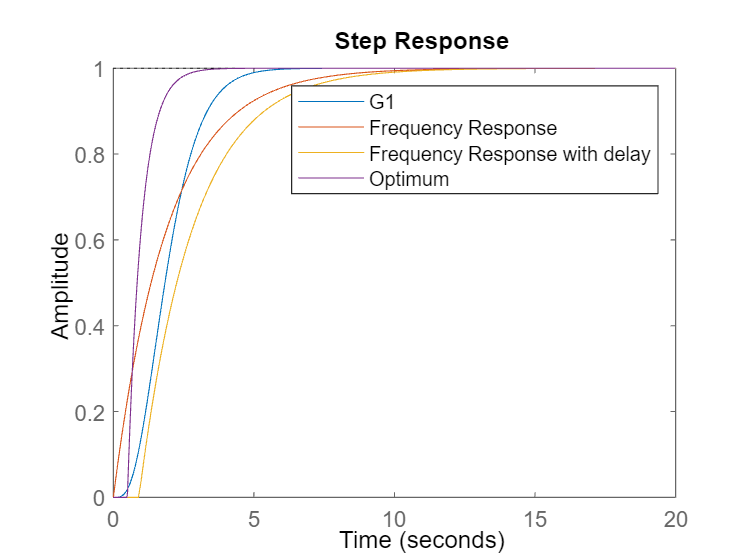

G_F_del = K_F*exp(-L_F*s) /(T_F*s+1);
G_F = K_F /(T_F*s+1);

% Transfer Function methode
%[K_T,L_T,T_T] = get_fod (G1,1)

%G_T = K_T*exp(-L_T*s) /(T_T*s+1);
% 
% Optimum methode
G_O = opt_app(G1, 0, 1, 1);
% % 
hold on;
step(G1);
step(G_F);
step(G_F_del)
%step(G_T);
step(G_O);
% 
legend ('G1' , 'Frequency Response' , 'Frequency Response with delay' , 'Optimum')

% 



## Design with opt

clc; clear; close all;

m = 1.5;
d = 0.05;
a = 2;
L = 3;
g = 9.81;

s =tf('s');

Plant = 5*m*g*d/(7*L*s^2); % R/Theta

Motor = 0.0274/(5*s*(0.003228*s + 0.003508));  %Theta/V

G = Motor * Plant   %   R/V

G =
 
          0.1008
  -----------------------
  0.3389 s^4 + 0.3683 s^3
 
Continuous-time transfer function.



isstable(G)

ans = logical
   0


%rlocus(G)

K = 53.8 * (s^3 + 1.087*s^2)/(s^3 + 8*s^2 + 24*s + 32)

K =
 
   53.8 s^3 + 58.48 s^2
  -----------------------
  s^3 + 8 s^2 + 24 s + 32
 
Continuous-time transfer function.



G1 = feedback(G*K, 1)

G1 =
 
                          5.423 s^3 + 5.895 s^2
  ---------------------------------------------------------------------
  0.3389 s^7 + 3.08 s^6 + 11.08 s^5 + 19.69 s^4 + 17.21 s^3 + 5.895 s^2
 
Continuous-time transfer function.





% K_TF = 1;
% L_TF = 0.5;
% T_TF = 0.5;
% 
% G_O = exp(-L_TF*s)*K_TF/(T_TF*s+1);
% 
% step(G_O)
% [Kc , pp , wc , wg] = margin(G_O);
% Tc = pi*2/wc;

[K_TF , L_TF, T_TF] = get_fod (G1);

G_F = K_TF /(T_TF*s+1)

G_F =
 
       1
  -----------
  1.936 s + 1
 
Continuous-time transfer function.



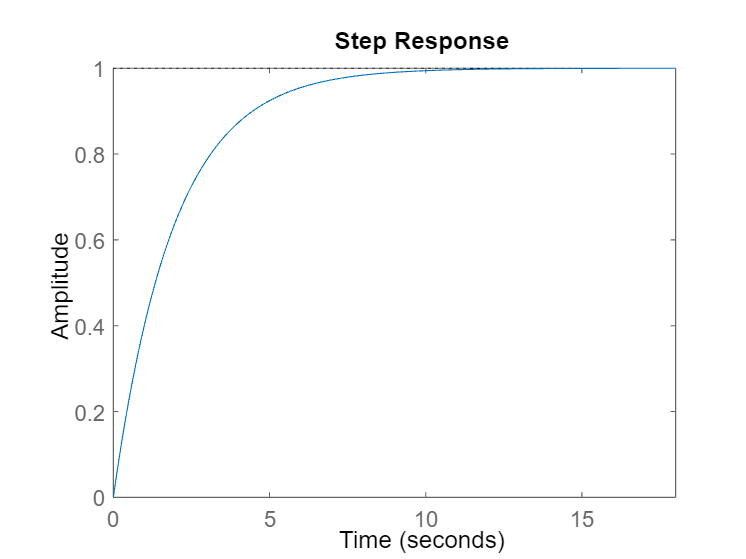

step(G_F)

N_F = 20;
[Kc , pp , wc , wg] = margin(G_F);
Tc = pi*2/wc;


## part 1

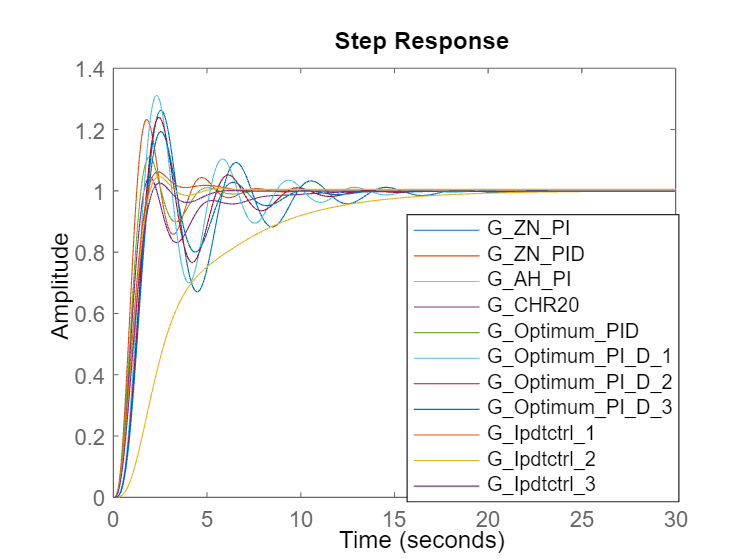

%%ZN
[ZN_PI , H0, Kp0 , Ti0 , Td0] = ziegler_nic(2,[K_TF , L_TF , T_TF , N_F]);
G_ZN_PI = feedback(G1 * ZN_PI ,1);

[ZN_PID , H1 , Kp1 , Ti1 , Td1] = ziegler_nic(3,[K_TF , L_TF , T_TF , N_F]);
G_ZN_PID = feedback(G1 * ZN_PID , 1);

%%Refined ZN
[K_c , pp , w_c , w_g] = margin(G_F);
T_c = (2*pi)/w_c;
vars = [K_TF,L_TF,T_TF, N_F, K_c, T_c];
[Gc_rZN, H,  ~, ~, ~, beta] = rziegler_nic(vars);

G_rZN = feedback(G1 * Gc_rZN, H);
% %hold on
% step(G_rZN)

%%Astrom Hagglund
[AH_PI , H2 , Kp2 , Ti2 , Td2] = astrom_hagglund(1,1,[K_TF , L_TF , T_TF , N_F]);
G_AH_PI = feedback(G1 * AH_PI , 1);

%%Astrom Hagglund Frequency
[frequency_based_AH_PI , H3 , Kp3 , Ti3 , Td3] = astrom_hagglund(1,2,[K_TF , Kc , Tc , N_F]);
G_AH_f_PI = feedback(G1 * frequency_based_AH_PI , 1);

%% CHR set point (20% Os) PID => key = 3, type = 1
Os = 20;
[Gc_CHR20, ~, ~, ~, ~] = chr_pid(3, 1, [K_TF , L_TF , T_TF , N_F, Os]);
G_CHR20 = feedback(G1 * Gc_CHR20, 1);

%%Optimum_PID
[Optimum_PID , H4 , Kp4 , Ti4 , Td4] = opt_pid(3,1,[K_TF , L_TF , T_TF , N_F , 1]);
G_Optimum_PID = feedback(G1 * Optimum_PID , 1);

%%Optimum_PI-D
[Optimum_PI_D_1 , H5 , Kp5 , Ti5 , Td5] = opt_pid(4,1,[K_TF , L_TF , T_TF , N_F , 1]);
G_Optimum_PI_D_1 = feedback(G1 * Optimum_PI_D_1 , H5);
[Optimum_PI_D_2 , H6 , Kp6 , Ti6 , Td6] = opt_pid(4,1,[K_TF , L_TF , T_TF , N_F , 2]);
G_Optimum_PI_D_2 = feedback(G1 * Optimum_PI_D_2 , H6);
[Optimum_PI_D_3 , H7 , Kp7 , Ti7 , Td7] = opt_pid(4,1,[K_TF , L_TF , T_TF , N_F , 3]);
G_Optimum_PI_D_3 = feedback(G1 * Optimum_PI_D_3 , H7);

%%IPDTCTRL
[Ipdtctrl1,~,~,~]=ipdtctrl(2,1,K_TF,L_TF,N_F);
G_Ipdtctrl_1 = feedback(G1 * Ipdtctrl1,1);
[Ipdtctrl2,~,~,~]=ipdtctrl(2,2,K_TF,L_TF,N_F);
G_Ipdtctrl_2 = feedback(G1 * Ipdtctrl2,1);
[Ipdtctrl3,~,~,~]=ipdtctrl(2,3,K_TF,L_TF,N_F);
G_Ipdtctrl_3 = feedback(G1 * Ipdtctrl3,1);



%Choosing Best One --> Optimum_PI-D ise
step(G_ZN_PI,G_ZN_PID ,G_AH_PI,G_CHR20 ,G_Optimum_PID,G_Optimum_PI_D_1,G_Optimum_PI_D_2,G_Optimum_PI_D_3,G_Ipdtctrl_1,G_Ipdtctrl_2,G_Ipdtctrl_3);
legend("Position", [0.58058,0.15865,0.29464,0.40119])

## Choosing Best

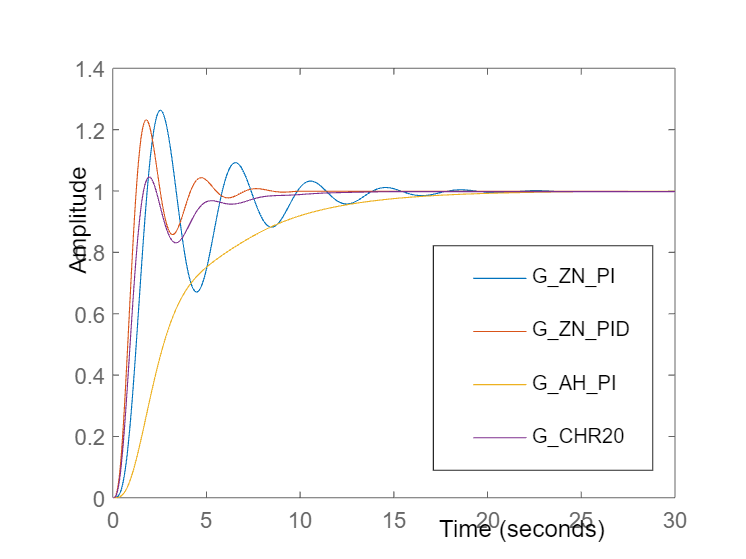

step(G_ZN_PI,G_ZN_PID,G_AH_PI,G_CHR20); % => G_ZN_PI
legend("Position", [0.58058,0.15865,0.29464,0.40119])

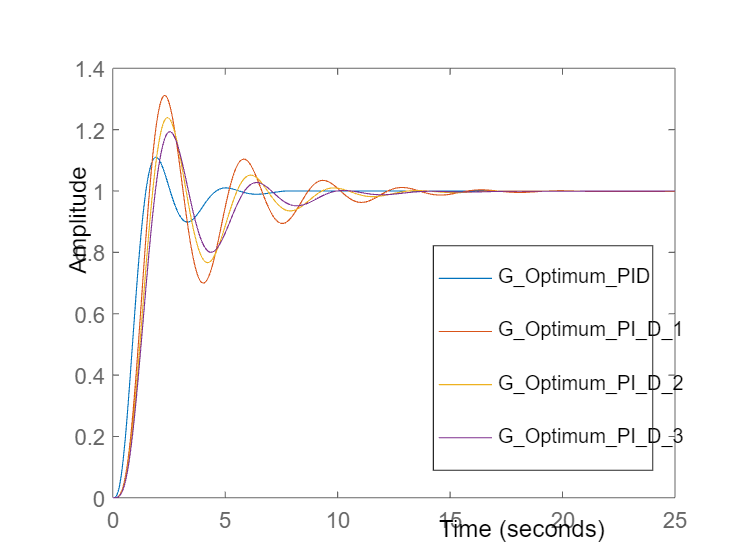


step(G_Optimum_PID,G_Optimum_PI_D_1,G_Optimum_PI_D_2,G_Optimum_PI_D_3);
legend("Position", [0.58058,0.15865,0.29464,0.40119]) % => none

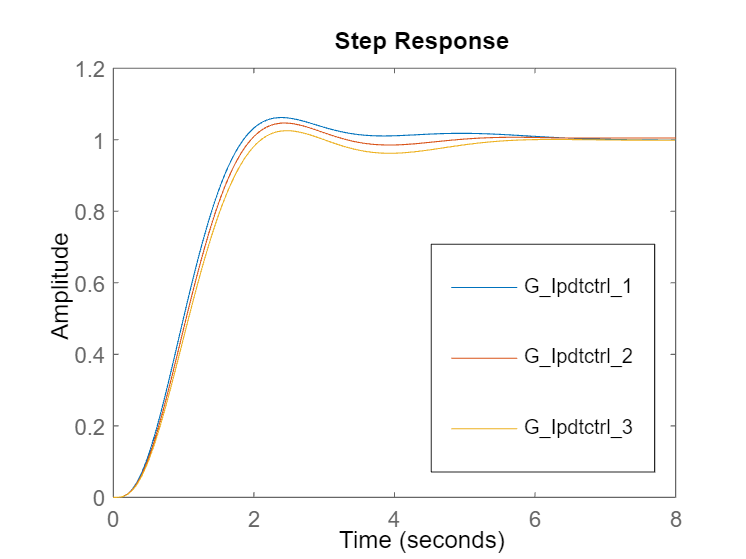


step(G_Ipdtctrl_1,G_Ipdtctrl_2,G_Ipdtctrl_3); % =>  none
legend("Position", [0.58058,0.15865,0.29464,0.40119])

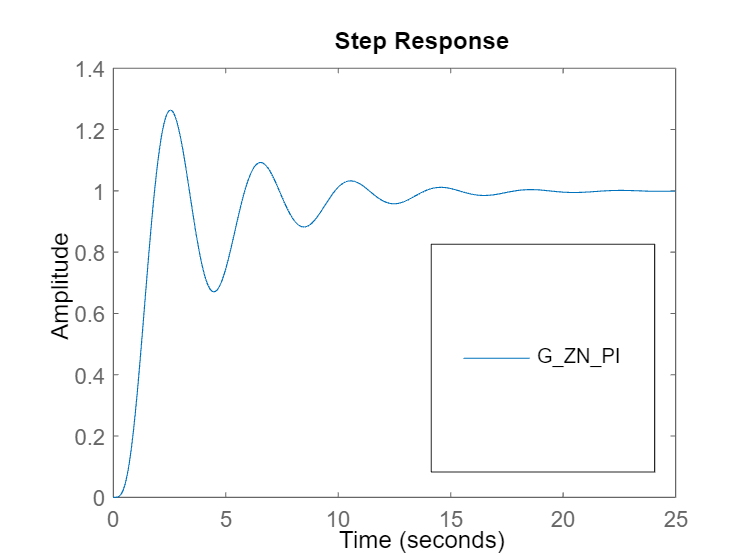


step(G_ZN_PI)
legend("Position", [0.58058,0.15865,0.29464,0.40119])

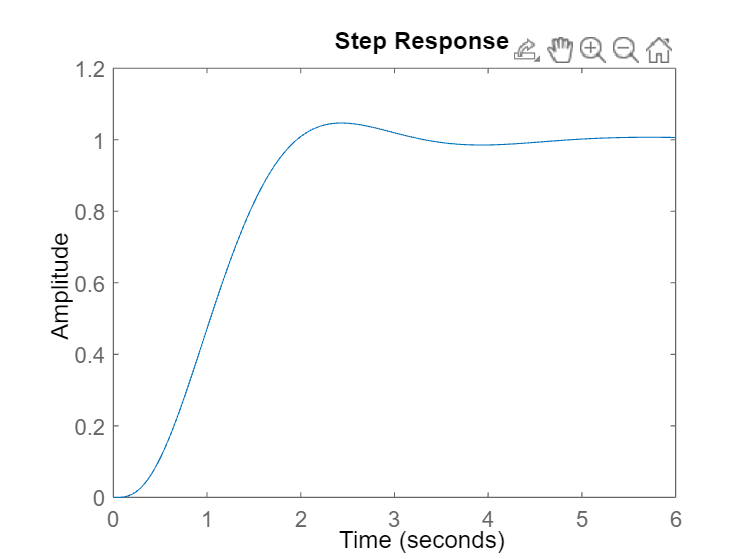


step(G_Ipdtctrl_2)

% G_ZN_PI = feedback(G1 * ZN_PI , 0.5);
% step(0.75*G_ZN_PI)
Ipdtctrl2

Ipdtctrl2 =
 
  0.7568 s^2 + 1.515 s + 0.9854
  -----------------------------
         0.02416 s^2 + s
 
Continuous-time transfer function.

